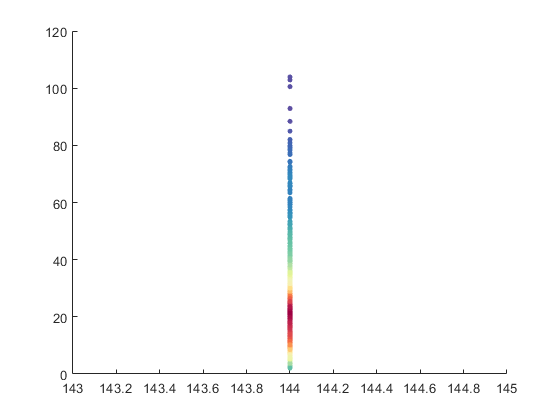

iFds =1;
fields = fieldnames(allDataCollect{1});
time_lag = 1:200;
fluoInt = zeros(numel(allDataCollect),2);

eachCellInt = [];
for iTime = 1:numel(allDataCollect)
    tempInt = zeros(size(allDataCollect{iTime}.(fields{iFds}),1),2);
    tempInt(:,1) = allDataCollect{iTime}.(fields{iFds});
    tempInt(:,2) = time_lag(iTime);
    eachCellInt = [eachCellInt;tempInt];
    try
        fluoInt(iTime,1) = mean(allDataCollect{iTime}.(fields{iFds}));
        fluoInt(iTime,2) = std(allDataCollect{iTime}.(fields{iFds}));
    catch
        msg = ['No cell was dectected in frame ',num2str(iTime),';',...
            ' Specify the ',fields{iFds}(4:end),' values as NaN.'];
        warning(msg);
        fluoInt(iTime,1) = NaN;
        fluoInt(iTime,2) = NaN;
    end
end
% map = colormap(parula(256));
% change_jet;
% map = newjet;
map =linspecer(256,'seq');

colorIdx = zeros(size(tempInt,1),1);
for i = 1:size(tempInt,1)
    [f,~] = ksdensity(tempInt(:,1),tempInt(i,1));
    
    colorIdx(i) = f;
end

colorIdx = rescale(colorIdx,1,256);
colorIdx = round(colorIdx);
tempInt(:,3) = colorIdx;


figure,scatter(tempInt(:,2),tempInt(:,1),15,map(tempInt(:,3),:),'filled','MarkerFaceAlpha',1);

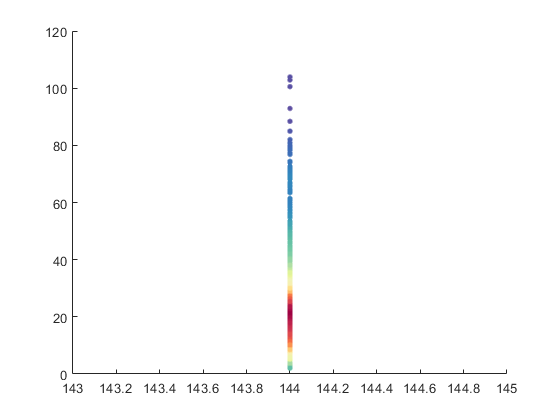


figure, 
for k = 1 :size(tempInt,1)
    line('Xdata',tempInt(k,2),'Ydata',tempInt(k,1), ...
        'LineStyle','none','Color',map(tempInt(k,3),:), ...
        'Marker','.','MarkerSize',12);
end

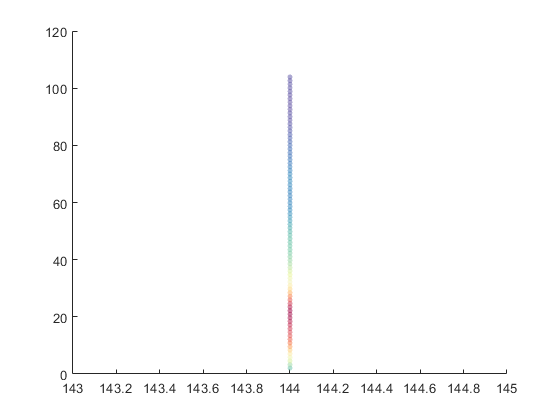

 
 for i = 1:size(tempInt,1)
    [f,xi] = ksdensity(tempInt(:,1));
    
 end
 
TF = xi > min(tempInt(:,1))&xi <= max(tempInt(:,1));
xi = xi(TF);
f = f(TF);
x = ones(size(xi))*tempInt(1,2);

colorIdx = rescale(f,1,256);
colorIdx = round(colorIdx);
figure,scatter(x,xi,15,map(colorIdx,:),'filled','MarkerFaceAlpha',0.5);

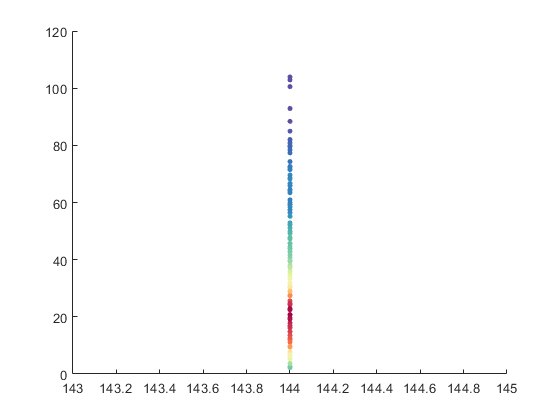


intValue = round(tempInt(:,1));
[C, ia, ic] = unique(intValue,'stable');
X = tempInt(ia,:);
figure,scatter(X(:,2),X(:,1),15,map(X(:,3),:),'filled','MarkerFaceAlpha',1);